clear all;
figure;

image = imread("TrainingPictures\RoadSituation_30kmh_Round_Building_Sunny_1.png");
%image = imread("TrainingPictures\RoadSituation_30kmh_Round_Vegetation_Sunny_1.png");
%image = imread("TrainingPictures\RoadSituation_50kmh_Round_Vegetation_Sunny_1.png");
%image = imread("TrainingPictures\RoadSituation_5kmh_Round_Air_Sunny_1.png");
%image = imread("TrainingPictures\RoadSituation_100kmh_Round_Air_Sunny_1.png");
%image = imread("TrainingPictures\RoadSituation_100kmh_Round_Street_Sunny_1.png");

tic
image_red = uint8(image(:, :, 1) - 1/2 * (image(:, :, 2) + image(:, :, 3)));

% fill all objects and binarize
image_red_bin = imbinarize(image_red, 'adaptive', 'Sensitivity', 0);
image_red_filled = imfill(image_red_bin, 'holes');

% get properties of circular objects
objects = regionprops('table', image_red_filled, "Circularity", "FilledArea", "BoundingBox", "Image");
objects = sortrows(objects, "FilledArea");

% get the first most matching objects
NUM_MATCHING_OBJECTS = 10;
if height(objects) < NUM_MATCHING_OBJECTS
    NUM_MATCHING_OBJECTS = height(objects)
end

filtered_objects = objects(end-NUM_MATCHING_OBJECTS+1:end, :);
toc

Elapsed time is 0.545018 seconds.



% get most round object
diff_circularity = abs(filtered_objects(:, :).Circularity - 1);
objects_circularity = table((1:height(filtered_objects))', filtered_objects(:, :).Circularity, diff_circularity, 'VariableNames', {'id', 'circularity', 'diff_circularity'});
objects_circularity = sortrows(objects_circularity, "diff_circularity");
object_of_choice_id = objects_circularity(1, :).id;
toc

Elapsed time is 0.630811 seconds.


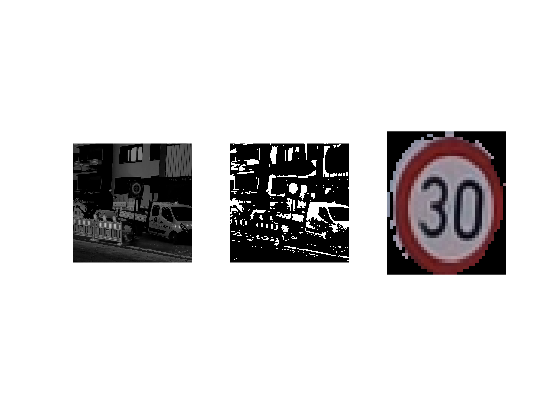

mask    = filtered_objects(object_of_choice_id,:).Image{1};
tmp_x       = floor(filtered_objects(object_of_choice_id, :).BoundingBox(1));
tmp_y       = floor(filtered_objects(object_of_choice_id, :).BoundingBox(2));
tmp_width   = width(mask) - 1;
tmp_height  = height(mask) - 1;
boxed_image = image(tmp_y:tmp_y+tmp_height, tmp_x:tmp_x+tmp_width, :);

boxed_image = boxed_image .* uint8(mask);

subplot(1,3,1), imshow(image_red);
subplot(1,3,2), imshow(image_red_filled);
subplot(1,3,3), imshow(boxed_image);

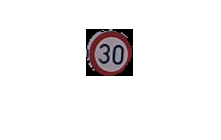

resized_image_size = max(size(boxed_image));
resized_image = imresize(boxed_image, [resized_image_size, resized_image_size]);

figure
imshow(resized_image)

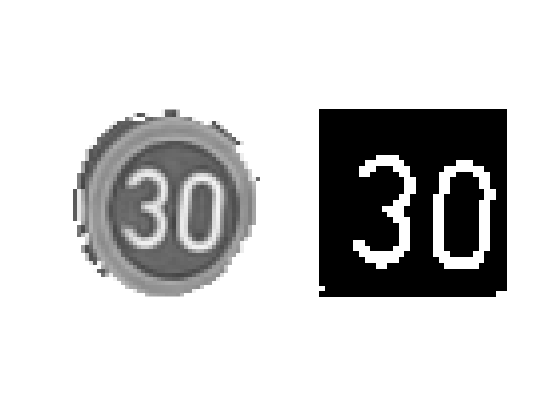

image_red = uint8(resized_image(:, :, 1) - 1/2 * (resized_image(:, :, 2) + resized_image(:, :, 3)));

resized_image_hsv = rgb2hsv(resized_image);

%image_red_bin = imbinarize(resized_image(1), 'adaptive', 'Sensitivity', 1);
%image_red_filled = imfill(image_red_bin, 'holes');

resized_image_hsv = imcomplement(resized_image_hsv(:,:,3));
resized_image_hsv_bin = imbinarize(resized_image_hsv, 'global');

resized_image_hsv_bin_size  = size(resized_image_hsv_bin);
default_width               = uint16(2/3 * resized_image_hsv_bin_size(1));
default_height              = uint16(2/3 * resized_image_hsv_bin_size(2));
half_default_width          = uint16(1/2 * default_width);
half_default_height         = uint16(1/2 * default_height);
center_x                    = uint16(1/2 * resized_image_hsv_bin_size(1));
center_y                    = uint16(1/2 * resized_image_hsv_bin_size(2));

number_image = resized_image_hsv_bin(center_x-half_default_width:center_x+half_default_width, center_y-half_default_height:center_y+half_default_height, :);

figure
subplot(1,2,1), imshow(resized_image_hsv)
subplot(1,2,2), imshow(number_image)

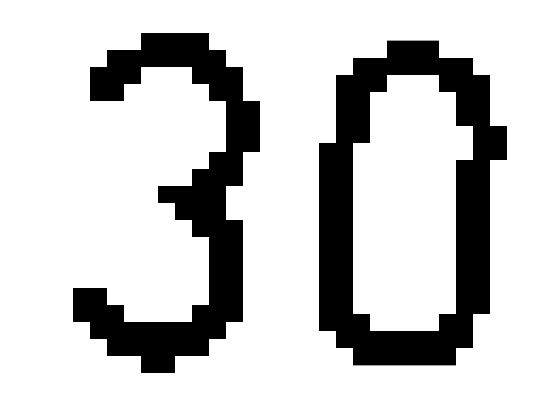

% extract single number
digit_images = regionprops('table', number_image, "Circularity", "FilledArea", "BoundingBox", "Image");
digit_images = sortrows(digit_images, "FilledArea");

idx = digit_images.FilledArea >= 30;
digit_images_filtered = digit_images(idx,:);

figure;
num_of_digits = height(digit_images_filtered);

for i_plot = 1:num_of_digits
    subplot(1,num_of_digits, i_plot); imshow(not(digit_images_filtered(i_plot,:).Image{1}));
end